# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** :제갈민우**

**학번**** :201911709**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : https://github.com/JegalMinwoo/-.git**

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 

n=[-200:200]; x= 5*[cos(0.49*pi*n) + cos(0.51*pi*n)]

x =    10.0000   -0.0000   -9.9803    0.0000    9.9211    0.0000   -9.8229    0.0000    9.6858   -0.0000   -9.5106   -0.0000    9.2978   -0.0000   -9.0483    0.0000    8.7631   -0.0000   -8.4433    0.0000    8.0902    0.0000   -7.7051    0.0000    7.2897   -0.0000   -6.8455   -0.0000    6.3742   -0.0000   -5.8779    0.0000    5.3583   -0.0000   -4.8175    0.0000    4.2578    0.0000   -3.6812    0.0000    3.0902   -0.0000   -2.4869    0.0000    1.8738   -0.0000   -1.2533    0.0000    0.6279   -0.0000


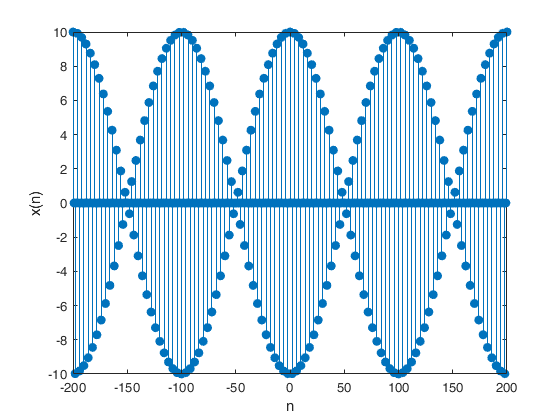

subplot(1,1,1); stem(n,x,'filled')
xlabel('n'); ylabel('x(n)');

2) 

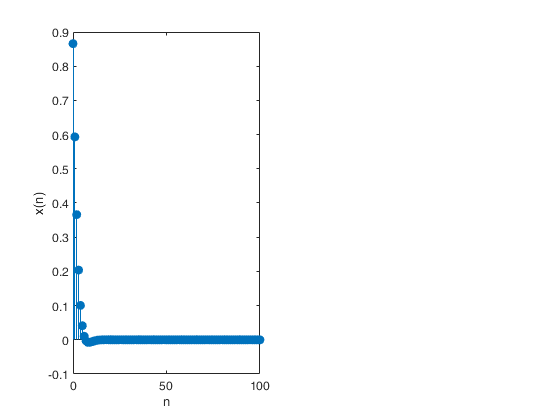

n=[0:100]; x=exp(-0.5*n).*sin(0.1*pi*n+pi/3);
subplot(1,2,1); stem(n,x,'filled');
xlabel('n'); ylabel('x(n)')

2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.


b=[1, 2, 1]; a=[1, -0.5, 0.25]; n=[0:100];
h = impz(b,a,n);
subplot(2,1,1); stem(n,h)
title('Impulse Response'); xlabel('n'); ylabel('h(n)')


2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)

sum(abs(h))

ans = 6.5714

3) 만약 이 시스템의 입력이  이면, filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

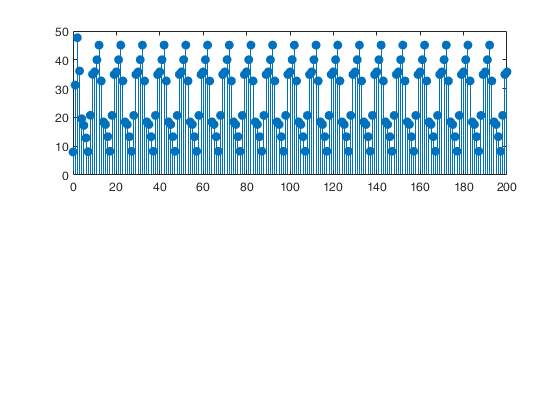

b=[1, 2, 1]; a=[1, -0.5, 0.25]; n=[0:200];
x= 5*ones(size(n))+3*cos(0.2*pi*n)+4*sin(0.6*pi*n); y=filter(b,a,x);
stem(n,y,'filled')

3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 

n= [0:50]; x=0.8.^n; h=(-0.9).^n;
y1=((0.8).^(n+1)-(-0.9).^(n+1))/(0.8+0.9);
subplot(1,3,1); stem(n,y1,'filled')
xlabel('n'); ylabel('y(n)')

2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. 

x2=x(1:26); h2=h(1:26); y2 = conv(h2,x2);
subplot(1,3,2); stem(n,y2,'filled')
xlabel('n'); ylabel('y(n)')


3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 

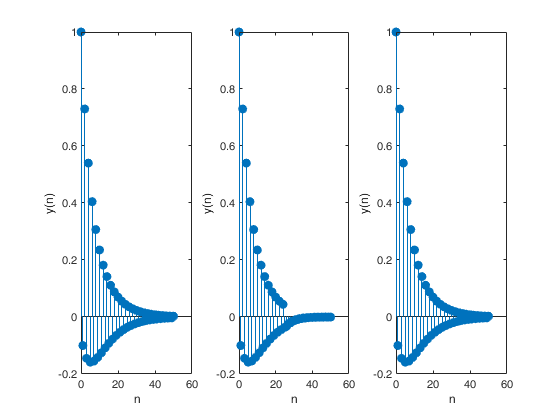

y3=filter([1],[1,0.9],x);
subplot(1,3,3); stem(n,y3,'filled');
xlabel('n'); ylabel('y(n)');

4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$

w = [-250:1:250]*pi/250;
H = 2*exp(j*w) ./ (exp(j*w) - 0.9*ones(1, 501));
magH = abs(H); angH = angle(H);
subplot(2,1,1); plot(w/pi,magH);
subplot(2,1,2); plot(w/pi,angH/pi);

2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$

w= [-250:1:250]*pi/250;
H= exp(j*w) ./ (exp(j*w) - 0.5*ones(1, 501)) +exp(j*w) ./ (exp(j*w) - 0.4*ones(1, 501))

H =    1.3810 + 0.0000i   1.3810 + 0.0054i   1.3810 + 0.0107i   1.3811 + 0.0161i   1.3812 + 0.0214i   1.3813 + 0.0268i   1.3814 + 0.0322i   1.3816 + 0.0375i   1.3818 + 0.0429i   1.3820 + 0.0482i   1.3822 + 0.0536i   1.3825 + 0.0590i   1.3828 + 0.0644i   1.3831 + 0.0697i   1.3835 + 0.0751i   1.3838 + 0.0805i   1.3842 + 0.0859i   1.3847 + 0.0913i   1.3851 + 0.0967i   1.3856 + 0.1021i   1.3861 + 0.1075i   1.3866 + 0.1129i   1.3872 + 0.1183i   1.3878 + 0.1237i   1.3884 + 0.1291i   1.3890 + 0.1345i   1.3897 + 0.1400i   1.3904 + 0.1454i   1.3911 + 0.1509i   1.3919 + 0.1563i   1.3926 + 0.1618i   1.3935 + 0.1673i   1.3943 + 0.1727i   1.3952 + 0.1782i   1.3961 + 0.1837i   1.3970 + 0.1892i   1.3979 + 0.1947i   1.3989 + 0.2002i   1.3999 + 0.2058i   1.4010 + 0.2113i   1.4020 + 0.2168i   1.4031 + 0.2224i   1.4043 + 0.2279i   1.4055 + 0.2335i   1.4066 + 0.2391i   1.4079 + 0.2447i   1.4091 + 0.2503i   1.4104 + 0.2559i   1.4118 + 0.2615i   1.4131 + 0.2672i


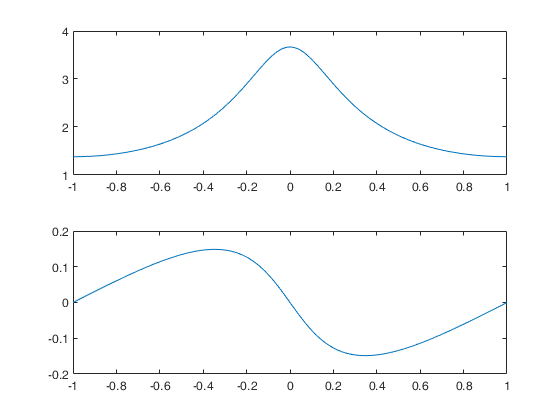

magH = abs(H); angH = angle(H);
subplot(2,1,1); plot(w/pi,magH);
subplot(2,1,2); plot(w/pi,angH/pi);

5. (P3.17) 

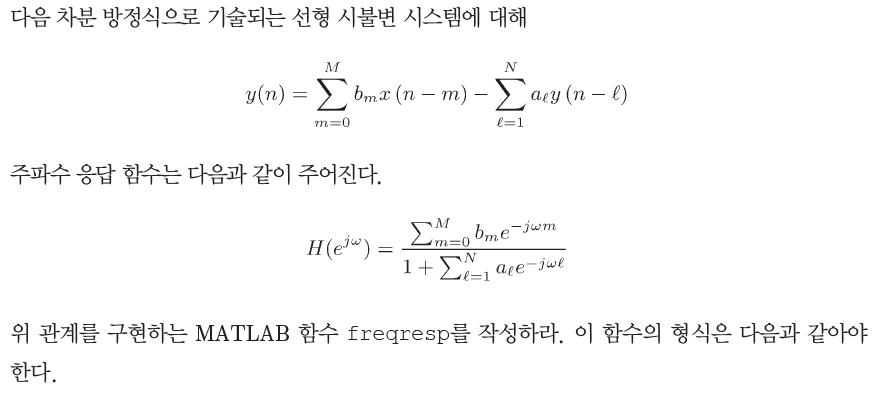

function [H] = freqresp(b,a,w)
% H = frequency response array evaluated at w frequencies
% b = numerator coefficient array
% a = denominator coefficient array (a(1) = 1)
% w = frequency location array
m=0:length(b)-1; num=b*exp(-j*m'*w);
l=0:length(a)-1; den=a*exp(-j*1'*w);
H=num./den;
end

6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$

w = [-300:300]*pi/300;
b = [1, -1];
a = [1, -0.95, 0.9025];
[H] = freqresp(b,a,w);
magH = abs(H); 
phaH = angle(H)*180/pi;
subplot(2,1,1); 
plot(w/pi,magH);
subplot(2,1,2); 
plot(w/pi,phaH);

2) $y\left(n\right)=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^n y\left(n-l\right)$

w = [-300:300]*pi/300;
l = [0:5];
b = [1];
a = [1 0.5.^l] ; 
[H] = freqresp(b,a,w);
magH = abs(H); 
phaH = angle(H)*180/pi;
subplot(2,1,1); 
plot(w/pi,magH);
subplot(2,1,2); 
plot(w/pi,phaH);

스크립트의 함수 정의는 파일의 끝에 표시되어야 합니다.
"freqresp" 함수 정의 뒤에 있는 모든 명령문을 첫 번째 로컬 함수 정의 앞으로 이동하십시오.